# Human wavelength discrimination

The cone absorptions are stochastic, following a Poisson distribution.  Hence, the number of absorptions differs from trial-to-trial. When we calculate the information availble to discriminate two lights, we must take into account not just the difference in mean but also the statistical difference between the cone absorptions.

This script calculates the information available in the cone absorptions to discriminate two small, uniform patches at two different wavelengths (520 and 530 nm).  We calculate the discriminability as we increase the mean intensity of the two signals. 

This script shows the distribution of the L,M and S absorptions caused by two stimuli, and it also shows how the distributions vary as the mean stimulus intensity level increases.

ieInit;

## Define the two stimuli

We image uniform fields of monochrome light on a human sensor.  These plots are made for two wavelengths and three scene intensity levels

wSamples  = [520  530];  nWave = length(wSamples);
luminance = [10 50 200]; nLevels = length(luminance);
sceneSize = 128;

% Make a scene for each of the wavelengths.
scene  = cell(1,nWave);

% We extract the cone absorptions for
% plotting into these variables
L = cell(1,length(wSamples));
M = cell(1,length(wSamples));
S = cell(1,length(wSamples));

## Create human optics and cone mosaic

The lens has an impact on the light transmitted to the retina.  The macular pigment and cone photopigments are also important.  This cell creates a standard human optics and a typical human cone mosaic.

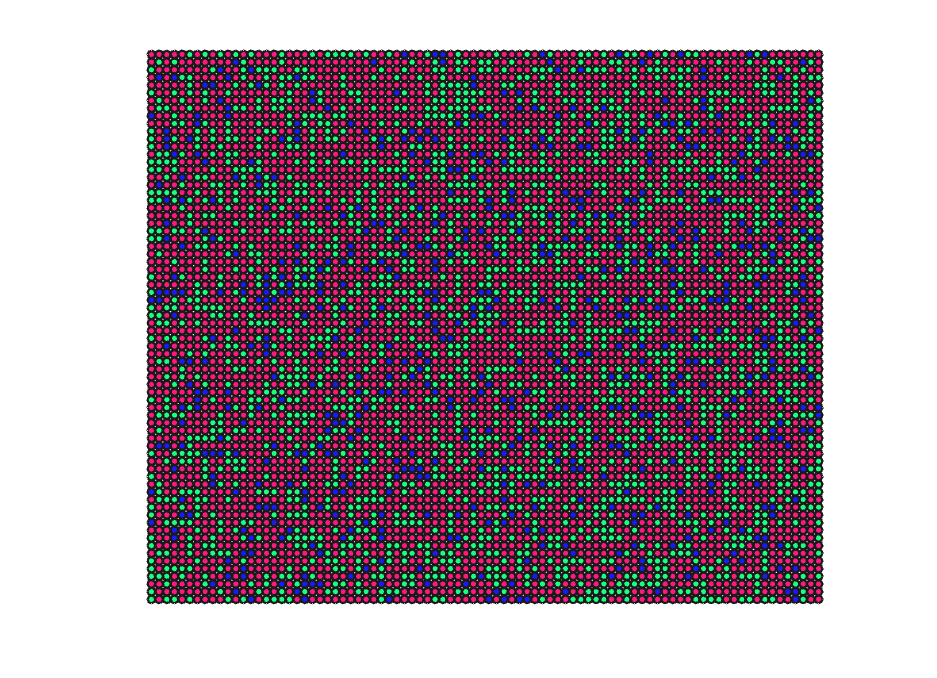

% Cone mosaic for 100 ms
cMosaic = coneMosaicRect;
cMosaic.integrationTime = 0.10;

% This is the mosaic
coneRectPlot(cMosaic,'cone mosaic');

## Calculate and plot the cone absorptions as 3D scatter plot

We make three graphs, one for each intensity level. Notice how the groups of points from the two different wavelengths separate as the scene intensity level increases.  

Also, notice how few S-cone absorptions there are compared to the L and M cone absorptions.

10 nm bandwidth
10 nm bandwidth


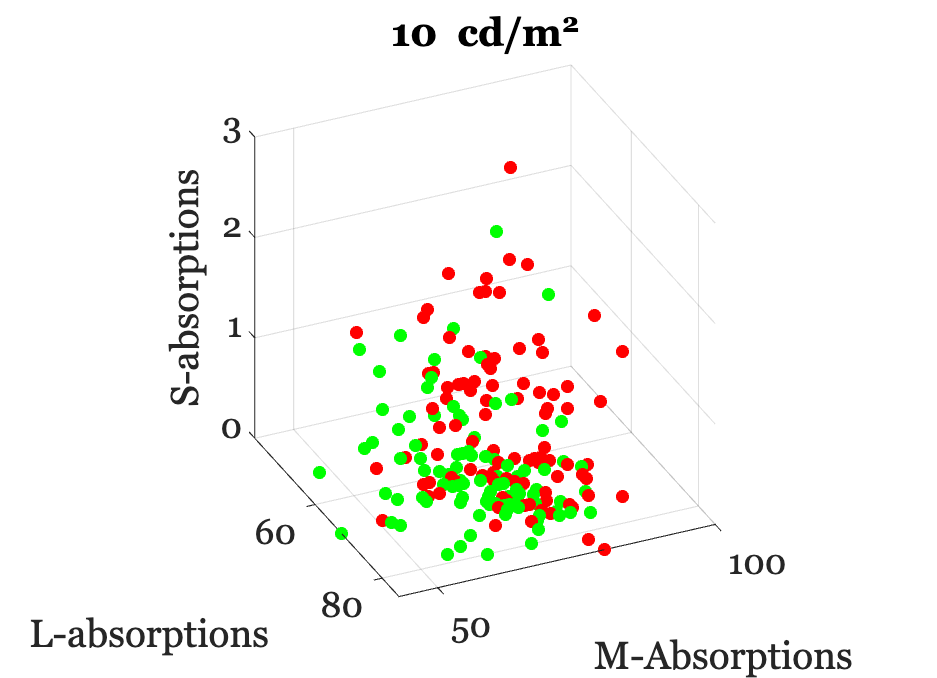

10 nm bandwidth
10 nm bandwidth


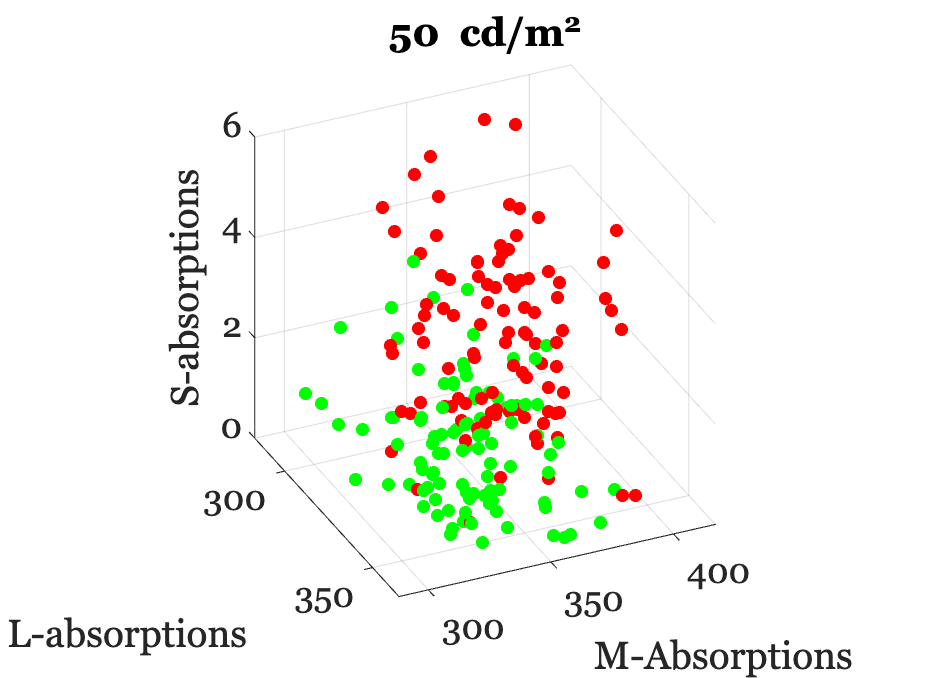

10 nm bandwidth
10 nm bandwidth


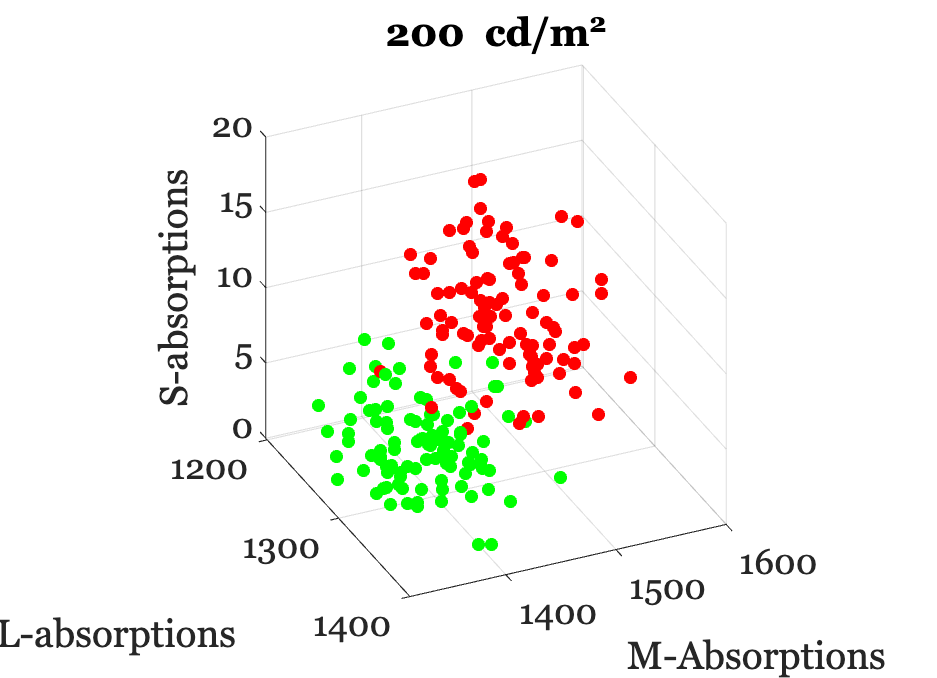

for rr = 1:nLevels  
    % For each luminance level create a new graph
    ieNewGraphWin;
    
    for ww=1:length(wSamples)  % For the two wavelength samples
        
        % Create a monochromatic scene and set the luminance
        scene{ww} = sceneCreate('uniform monochromatic',wSamples(ww),sceneSize);
        scene{ww} = sceneAdjustLuminance(scene{ww},luminance(rr));
        
        % Human optics
        oi = oiCreate('human');

        % Compute the retinal spectral irradiance
        oi = oiCompute(oi,scene{ww},'pad value','mean');
        
        % Compute the cone absorptions
        cMosaic.compute(oi);
        
        % Retrieve the cone absorptions
        L{ww} = cMosaic.coneAbsorptions('coneType','l');
        M{ww} = cMosaic.coneAbsorptions('coneType','m');
        S{ww} = cMosaic.coneAbsorptions('coneType','s');
        
        % There are different numbers of
        % L,M and S cones. We truncate to the same length for
        % simplicity in plotting.
        n = min(100,length(L{ww}));
        S{ww} = S{ww}(1:n); M{ww} = M{ww}(1:n); L{ww} = L{ww}(1:n);
    end
    
    % Plot the L,M,S absorptions for this luminance level 
    az = 65.5; el = 30;
    for ww=1:length(wSamples)
        scatter3(L{ww}(:),M{ww}(:),S{ww}(:),'filled')
        hold on; view([az el]); axis square; grid on
        xlabel('L-absorptions'); ylabel('M-Absorptions');
        zlabel('S-absorptions'); 
    end
    title(sprintf('%.0f cd/m^2',luminance(rr)));
end